# Application: State and Output Trajectories of LTI Systems using Laplace Transform - Example 1

## Introduction

Symbolic workflows keep calculations in their natural symbolic form rather than numerical form. This approach helps to understand the solution's properties and uses exact symbolic values. Numbers are substituted for symbolic variables only when a numerical result is required or cannot be continued in a symbolic manner.  

Typically, the steps are:

- Declare the variables and the (state and output) equations.

- Solve the equations using the Laplace transform.

- Substitute numerical values.

- Plot the results.

- Analyse the results.

## LTI System of 1st Order: a Series RC Circuit

We want to determine state and output trajectories for the LTI system:

        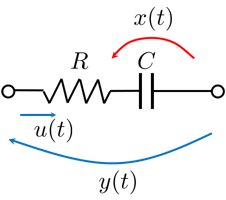     


$$\left\{ \begin{array}{rcl}
\dot{x}(t) &=& \frac{1}{C} u(t)\\
y(t) &=& x(t) + Ru(t)
\end{array} \right.$$


with initial condition $x(0) = x_)\,$ and input $u(t) = A \cos(\omega t) \cdot 1(t)\,$

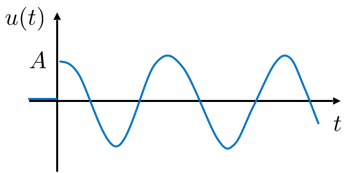

### Step 0: Declare the Variables

clear

syms t s x(t) y(t) u(t) X Y C R A omega % the variables 
                                      % in the time and frequency domain

assume(t >=0)
assume([A C R omega] >0) % a compact way to declare A, C, R and omega as positive real
                         % symbolic variables


u(t) = A * cos(omega * t) % Note: you DO NOT NEED to explicity write the Heaviside function!

$$u(t) = A\,\cos\left(\omega \,t\right)$$

x0VAL = -1.45; % the initial condition [V]
Aval = 2.50;  % V
Cval = 1.5;   % F
Rval = 10.0;  % Ohm
OMval = 2*pi*0.1; % rad/s

### Step 1: Declare the LTI Equations 

Firstly, declare the symbolic derivative $\dot x$ of the state $x(t)$ 

dot_x = diff(x,t);


Then, declare the ODE state equation and the algebraic output equation. **Pay attention to the == symbols**

eqnX = dot_x  == (1/C) * u; % state eq.
eqnY = y == x+R*u;              % output eq.

What does the equations look like?

disp(eqnX)

$$\frac{\partial }{\partial t}x\left(t\right)=\frac{A\,\cos\left(\omega \,t\right)}{C}$$

disp(eqnY)

$$y\left(t\right)=x\left(t\right)+A\,R\,\cos\left(\omega \,t\right)$$

### Step 2: Solve the ODE Using the Laplace Transform 

Let's compute the Laplace transform of the ODE:

eqnLT = laplace(eqnX, t, s);

What does the equation in the Laplace transform domain look like?

disp(eqnLT)

$$s\,\mathrm{laplace}\left(x\left(t\right),t,s\right)-x\left(0\right)=\frac{A\,s}{C\,\left(\omega^{2}+s^{2}\right)}$$

**Note**: In order to continue and solve the algebraic equation with the Laplace transform, we must replace all terms indicating Laplace transforms of the function $x(t)$ with the symbolic variable $X$ corresponding to the Laplace transform $X(s)$ .

eqnLT1 = subs(eqnLT,laplace(x,t,s),X)

$$eqnLT1 = X\,s-x\left(0\right)=\frac{A\,s}{C\,\left(\omega^{2}+s^{2}\right)}$$

What about the **output equation**? Let's compute the Laplace transform of the output equation:

eqnYLT = laplace(eqnY, t, s);
disp(eqnYLT)

$$\mathrm{laplace}\left(y\left(t\right),t,s\right)=\mathrm{laplace}\left(x\left(t\right),t,s\right)+\frac{A\,R\,s}{\omega^{2}+s^{2}}$$

**Note**: In order to continue and solve the algebraic equation with the Laplace transform, we must replace all terms indicating Laplace transforms of the function $x(t)$ and $y(t)$ with the symbolic variables $X$, $Y$, corresponding to the Laplace transforms $X(s)$ and $Y(s)$.

eqnY_LT1 = subs(eqnYLT,[laplace(x,t,s) laplace(y,t,s)],[X Y]);
disp(eqnY_LT1)

$$Y=X+\frac{A\,R\,s}{\omega^{2}+s^{2}}$$

Finally, **solve the ODE**

Xsol = solve(eqnLT1, X)

$$Xsol = \frac{x\left(0\right)+\frac{A\,s}{C\,\left(\omega^{2}+s^{2}\right)}}{s}$$

Xsol = simplify(expand(Xsol))

$$Xsol = \frac{x\left(0\right)}{s}+\frac{A}{C\,\left(\omega^{2}+s^{2}\right)}$$

Let's **apply the inverse Laplace transform**:

xsol = ilaplace(Xsol)

$$xsol = x\left(0\right)+\frac{A\,\sin\left(\omega \,t\right)}{C\,\omega }$$

That's it!

eqnY_LT1 = subs(eqnY_LT1,X,Xsol)

$$eqnY\_LT1 = Y=\frac{x\left(0\right)}{s}+\frac{A}{C\,\left(\omega^{2}+s^{2}\right)}+\frac{A\,R\,s}{\omega^{2}+s^{2}}$$


Ysol = solve(eqnY_LT1,Y)

$$Ysol = \frac{x\left(0\right)}{s}+\frac{A}{C\,\left(\omega^{2}+s^{2}\right)}+\frac{A\,R\,s}{\omega^{2}+s^{2}}$$

ysol = ilaplace(Ysol)

$$ysol = x\left(0\right)+\frac{A\,\left(\sin\left(\omega \,t\right)+C\,R\,\omega \,\cos\left(\omega \,t\right)\right)}{C\,\omega }$$

### Step 3: Substitute Numerical Values

xSol_IC = subs(xsol, x(0), x0VAL)

$$xSol\_IC = \frac{A\,\sin\left(\omega \,t\right)}{C\,\omega }-\frac{29}{20}$$

xSol_IC = subs(xSol_IC, [A C R omega], [Aval Cval Rval OMval])

$$xSol\_IC = \frac{25\,\sin\left(\frac{\pi \,t}{5}\right)}{3\,\pi }-\frac{29}{20}$$


ySol_IC = subs(ysol, x(0), x0VAL)

$$ySol\_IC = \frac{A\,\left(\sin\left(\omega \,t\right)+C\,R\,\omega \,\cos\left(\omega \,t\right)\right)}{C\,\omega }-\frac{29}{20}$$

ySol_IC = subs(ySol_IC, [A C R omega], [Aval Cval Rval OMval])

$$ySol\_IC = \frac{25\,\left(\sin\left(\frac{\pi \,t}{5}\right)+3\,\pi \,\cos\left(\frac{\pi \,t}{5}\right)\right)}{3\,\pi }-\frac{29}{20}$$

### Step 4: Plot the results.

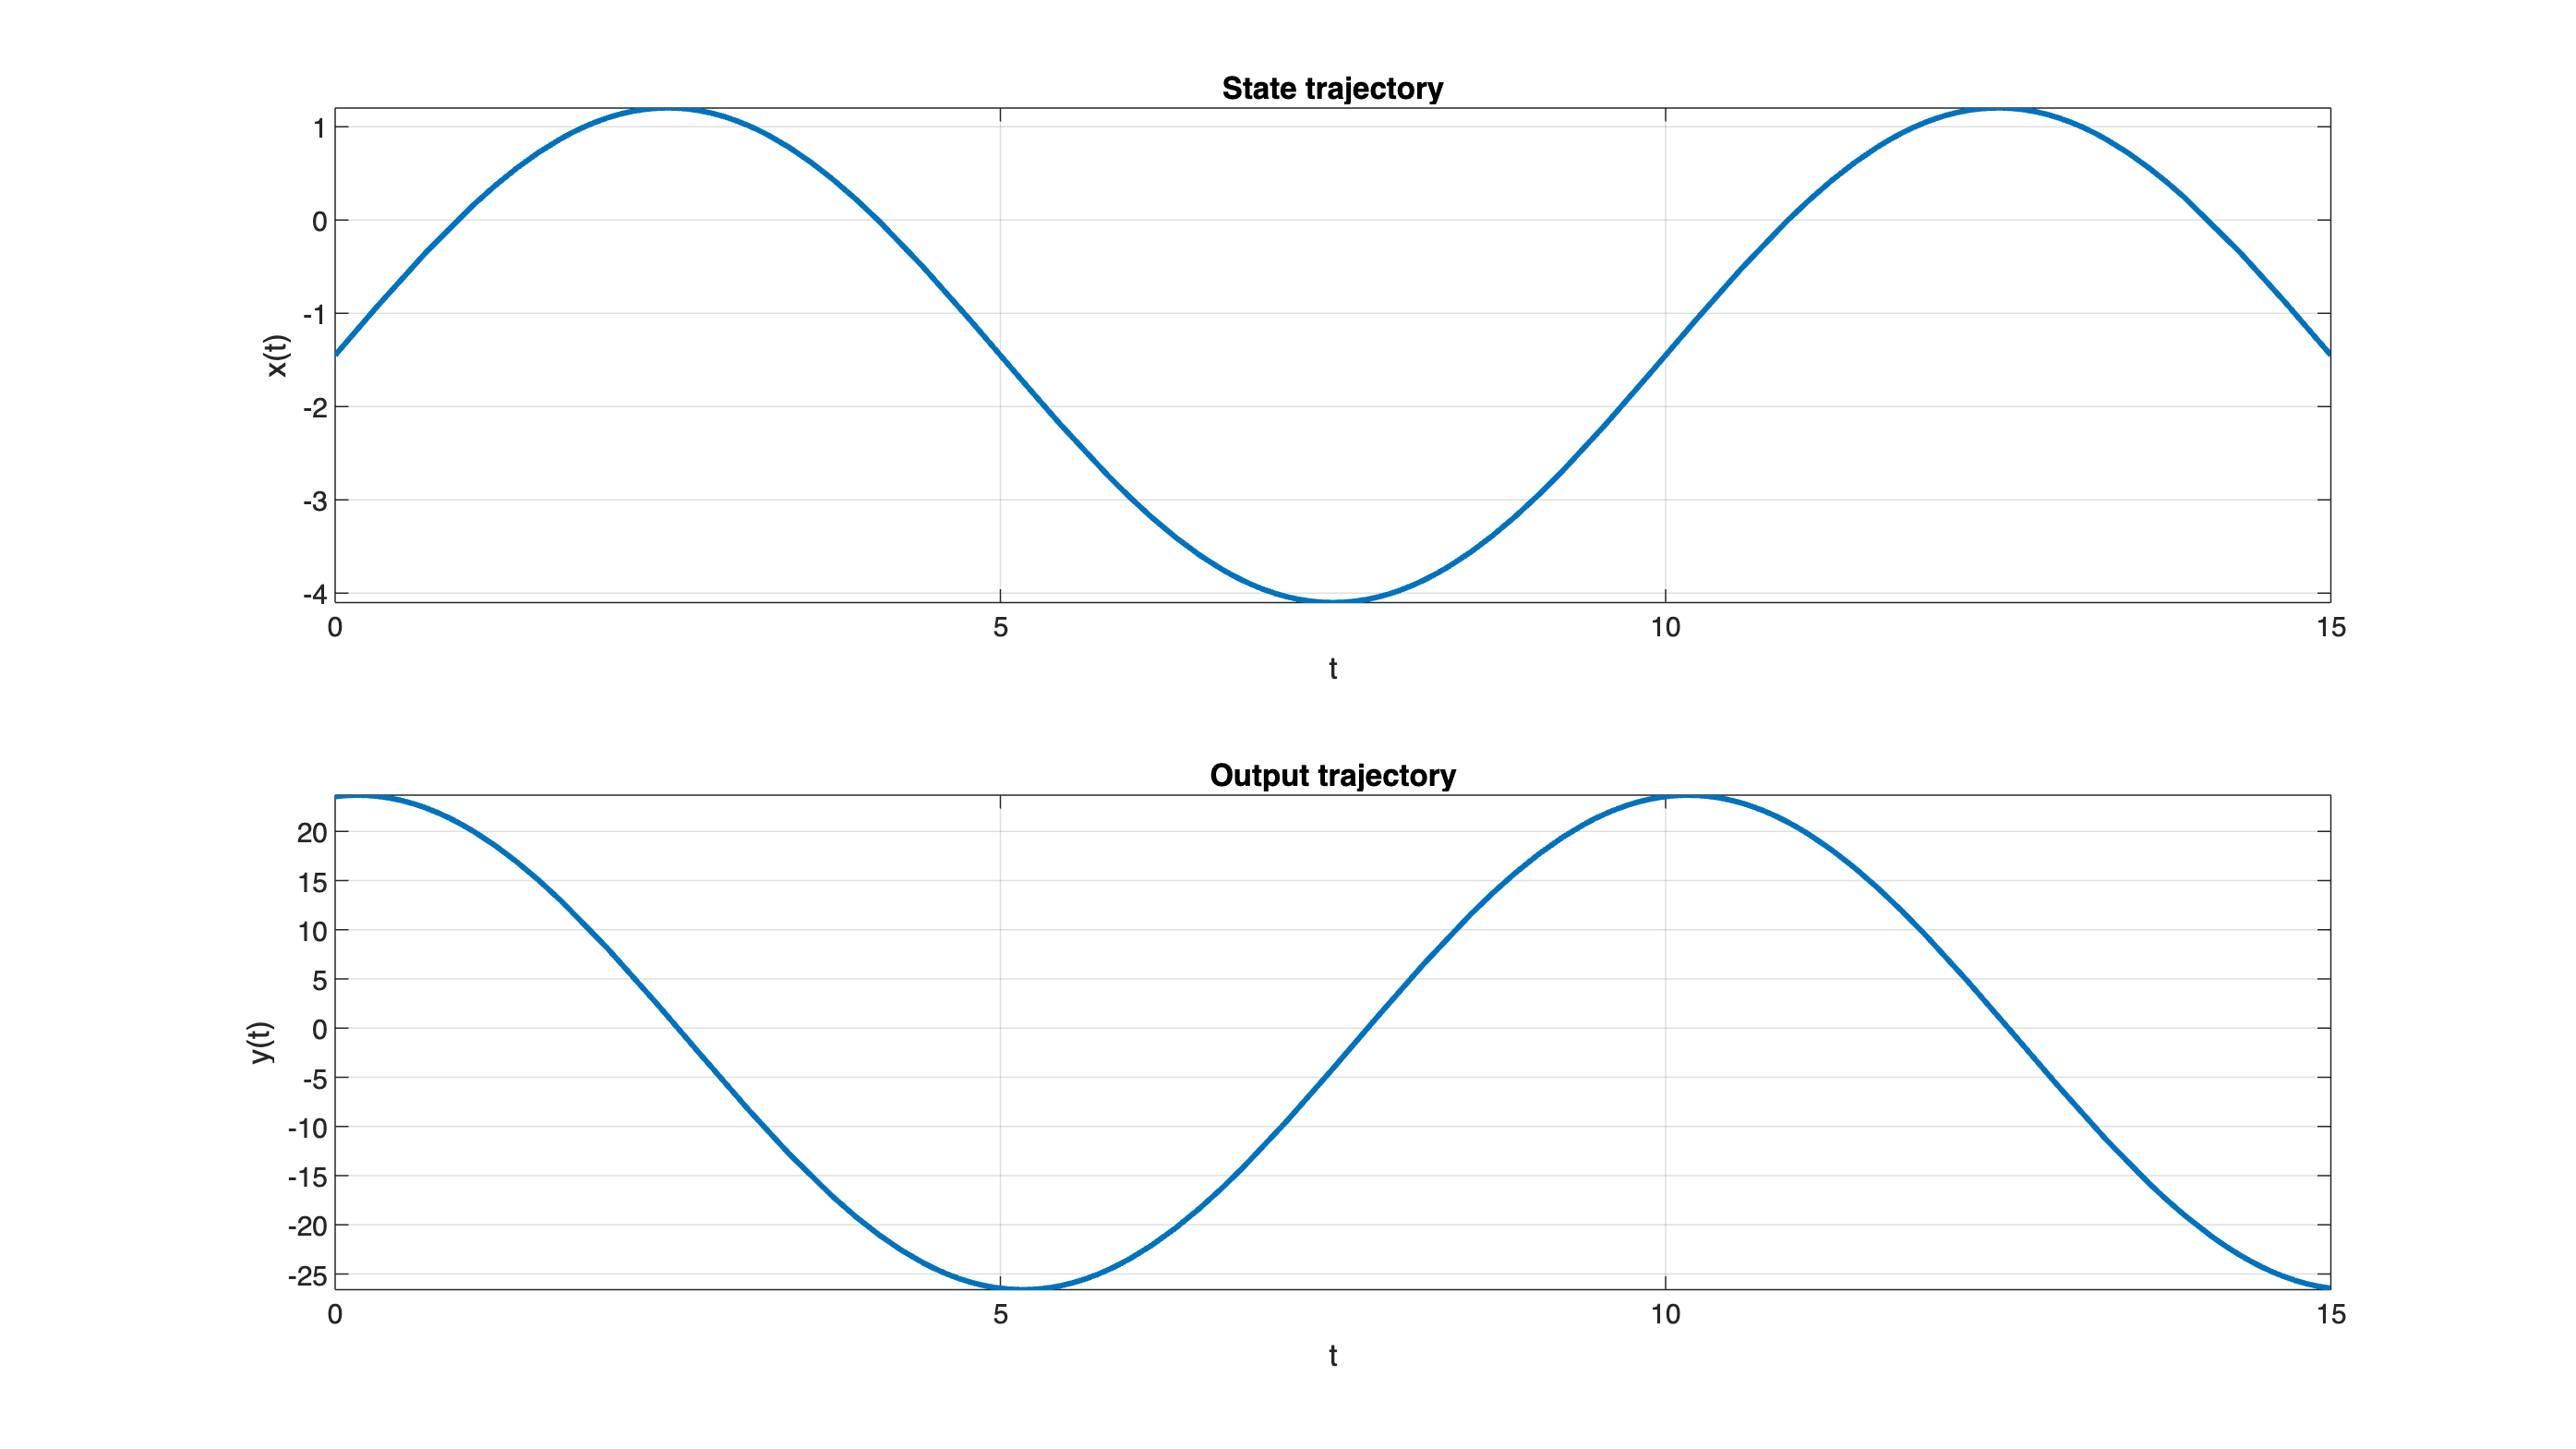

figure('Units','normalized','Position',[0.1,0.1,0.9,0.9])

subplot(2,1,1)
fplot(xSol_IC,[0 15], 'LineWidth',2)                      
title('State trajectory')
ylabel('x(t)')
xlabel('t')
grid on
subplot(2,1,2);
fplot(ySol_IC,[0 15], 'LineWidth',2)                        
title('Output trajectory')
ylabel('y(t)')
xlabel('t')
grid on